## AUTOMATIC ACQUISITION

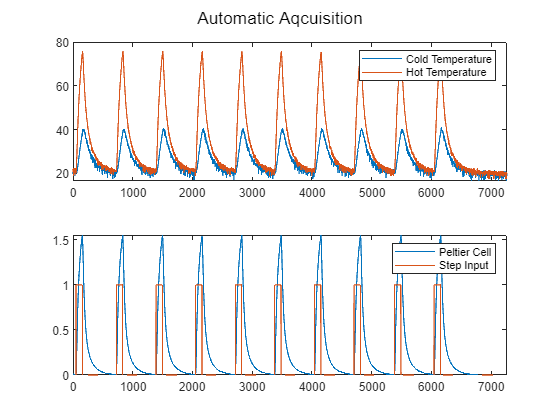

clear
load acquisizione_ventola_automatica.mat

cold_temperature=data(:,1);
hot_temperature=data(:,2);
step_input=data(:,4);
v_peltier=data(:,3);

N=length(cold_temperature);

Ts=0.25;
t=0:0.25:0.25*(N-1);

figure;
subplot(2,1,1);
%plot(t,[smooth(cold_temperature),smooth(hot_temperature)]);
plot(t,[cold_temperature,hot_temperature]);
legend('Cold Temperature','Hot Temperature')
xlim([0,Ts*N])
subplot(2,1,2);
plot(t,[v_peltier,step_input]);
xlim([0,Ts*N])
legend('Peltier Cell','Step Input')
sgtitle('Automatic Aqcuisition')

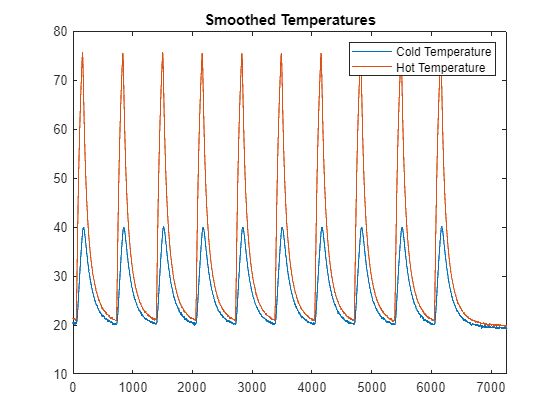


figure;
plot(t,[smooth(cold_temperature,15),smooth(hot_temperature,15)]);
legend('Cold Temperature','Hot Temperature')
xlim([0,Ts*N])
title('Smoothed Temperatures')


start_val=15360;

v_peltier_id=v_peltier(1:start_val-1);
v_peltier_val=v_peltier(start_val:end);

step_input_id=step_input(1:start_val-1);
step_input_val=step_input(start_val:end);




## AUTOMATIC ACQUISITION WITH MILLIS

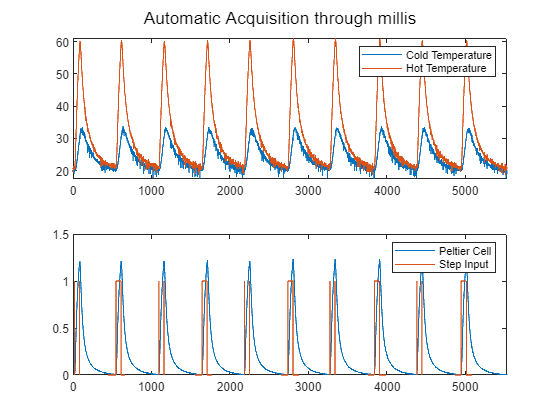

clear
load acquisizione_ventola_automatica_millis.mat

cold_temperature=data(:,1);
hot_temperature=data(:,2);
step_input=data(:,4);
v_peltier=data(:,3);

N=length(cold_temperature);

Ts=0.25;
t=0:0.25:0.25*(N-1);

figure;
subplot(2,1,1);
%plot(t,[smooth(cold_temperature),smooth(hot_temperature)]);
plot(t,[cold_temperature,hot_temperature]);
legend('Cold Temperature','Hot Temperature')
xlim([0,Ts*N])
subplot(2,1,2);
plot(t,[v_peltier,step_input]);
xlim([0,Ts*N])
legend('Peltier Cell','Step Input')
sgtitle('Automatic Acquisition through millis')

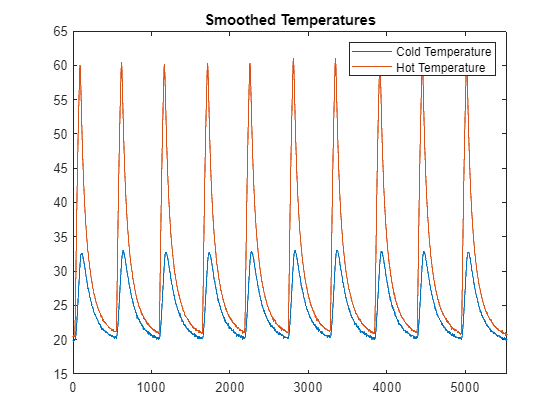


figure;
plot(t,[smooth(cold_temperature,15),smooth(hot_temperature,15)]);
legend('Cold Temperature','Hot Temperature')
xlim([0,Ts*N])
title('Smoothed Temperatures')


start_val=15360;

v_peltier_id=v_peltier(1:start_val-1);
v_peltier_val=v_peltier(start_val:end);

step_input_id=step_input(1:start_val-1);
step_input_val=step_input(start_val:end);

## AUTOMATIC ACQUISITION PRE-FIX

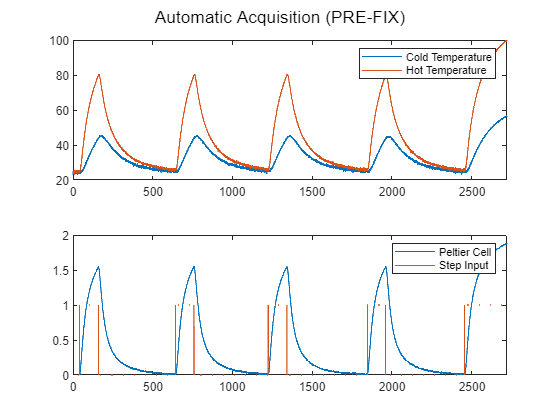

clear
load dataAutomaticWithFan.mat

cold_temperature=data(:,1);
hot_temperature=data(:,2);
step_input=data(:,4);
v_peltier=data(:,3);

N=length(cold_temperature);

Ts=0.25;
t=0:0.25:0.25*(N-1);

figure;
subplot(2,1,1);
%plot(t,[smooth(cold_temperature),smooth(hot_temperature)]);
plot(t,[cold_temperature,hot_temperature]);
legend('Cold Temperature','Hot Temperature')
xlim([0,Ts*N])
subplot(2,1,2);
plot(t,[v_peltier,step_input]);
xlim([0,Ts*N])
legend('Peltier Cell','Step Input')
sgtitle('Automatic Acquisition (PRE-FIX)')

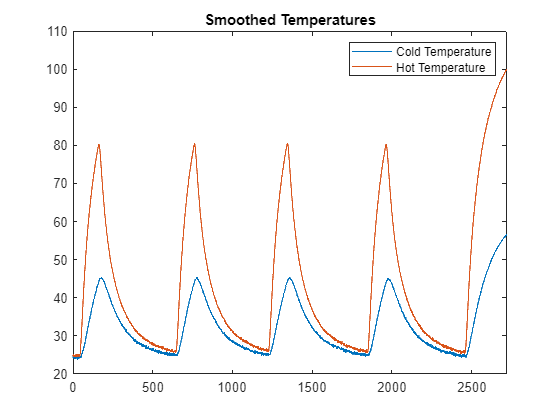


figure;
plot(t,[smooth(cold_temperature),smooth(hot_temperature)]);
legend('Cold Temperature','Hot Temperature')
xlim([0,Ts*N])
title('Smoothed Temperatures')